# Part 7: Demonstration

## Exercise 7.1: Navigating a 3D maze

For this exercise we first get the route:

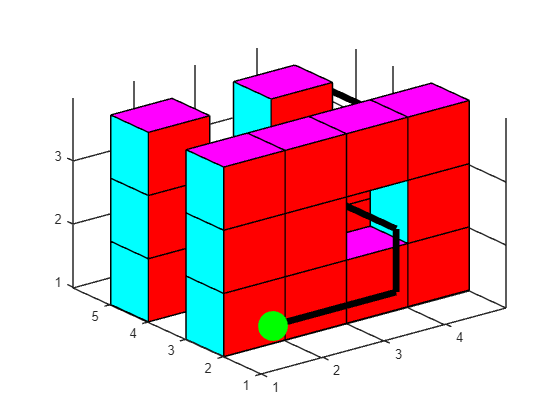

run("maze/exercise_4_files/map_script_3d.m"); % Either need route or route scaled

which defines the route variable. Then we scale it according to the relative map size in the real track:

%% Scale the route
x_scale = 0.61;
y_scale = 0.535;
z_scale = 0.725;

x_offset = 0.3;
y_offset = 0.5;
z_offset = 0.25;

% Make a copy of the route
route_scaled = route;

% Scale the copy
route_scaled(:,1) = (route_scaled(:,1) - 1) * x_scale + x_offset;
route_scaled(:,2) = (route_scaled(:,2) - 1) * y_scale + y_offset;
route_scaled(:,3) = (route_scaled(:,3) - 1) * z_scale + z_offset;

% Print the scaled route
route_scaled

route_scaled =     0.3000    0.5000    0.2500
    0.9100    0.5000    0.2500
    1.5200    0.5000    0.2500
    1.5200    0.5000    0.9750
    1.5200    1.0350    0.9750
    1.5200    1.5700    0.9750
    1.5200    1.5700    1.7000
    2.1300    1.5700    1.7000
    2.1300    2.1050    1.7000
    2.1300    2.6400    1.7000


At last, we initalize the parameters that must be defined for the simulation to work:

wall_color = [0.8 0.2 0.2];
sample_time = 4e-2;
publish_rate = 1 * sample_time;
x0 = 36;
y0 = 80;
z0 = 1;
g = 9.80665;
mass_drone = 0.32 ;
mass_rod = 0.0;
mass_tip = 0;
mass_total = mass_drone + mass_rod + mass_tip;
stiffness_rod = 100 ;
critical_damping_rod = 2 * sqrt(mass_total * stiffness_rod) ;
stiffness_wall = 100 ;
critical_damping_wall = 2 * sqrt(mass_total * stiffness_wall) ;
inertia_xx = 0.007 ;
inertia_yy = 0.007 ;
inertia_zz = 0.012 ;
arm_length = 0.17 ;
rotor_offset_top = 0.01 ;
motor_constant = 8.54858e-06 ;
moment_constant = 0.016 ;
max_rot_velocity = 838 ;
allocation_matrix = ...
    [1 1 1 1
     0 arm_length 0 -arm_length
     -arm_length 0 arm_length 0
     -moment_constant moment_constant -moment_constant moment_constant] ;
mix_matrix = inv(motor_constant * allocation_matrix) ;
air_density = 1.2041;
drag_coefficient = 0.47;
reference_area = pi * 75e-3^2;

We the run the simulation file *'uas_main_exe_7_1.slx*' and watch the drone fly.

## Exercise 7.2: Poting the position controller to the real system

### Exercise 7.2.1: Finding the relation between PWN and vertical accelleration

For this task we first need to find the relation between PWN thrust values and the vertical accelleration which can be done through linear fitting. 

We use the uas_main_exe_7_2.slx model as this has been reprogrammed tol the joystick. Use the following parameters:

clc; clear all; close all;

% Environment parameters
wall_color = [0.8 0.2 0.2];
sample_time = 4e-2;
publish_rate = 1 * sample_time;
g = 9.80665;
mass_drone = 0.042 ;
mass_rod = 0.0;
mass_tip = 0;
mass_total = mass_drone + mass_rod + mass_tip;
stiffness_rod = 100 ;
critical_damping_rod = 2 * sqrt(mass_total * stiffness_rod) ;
stiffness_wall = 100 ;
critical_damping_wall = 2 * sqrt(mass_total * stiffness_wall) ;
inertia_xx = 0.007 ;
inertia_yy = 0.007 ;
inertia_zz = 0.012 ;
arm_length = 0.17 ;
rotor_offset_top = 0.01 ;
motor_constant = 8.54858e-06 ;
moment_constant = 0.016 ;
max_rot_velocity = 838 ;
allocation_matrix = ...
    [1 1 1 1
     0 arm_length 0 -arm_length
     -arm_length 0 arm_length 0
     -moment_constant moment_constant -moment_constant moment_constant] ;
mix_matrix = inv(motor_constant * allocation_matrix) ;
air_density = 1.2041;
drag_coefficient = 0.47;
reference_area = pi * 75e-3^2;

#### Plotting the data

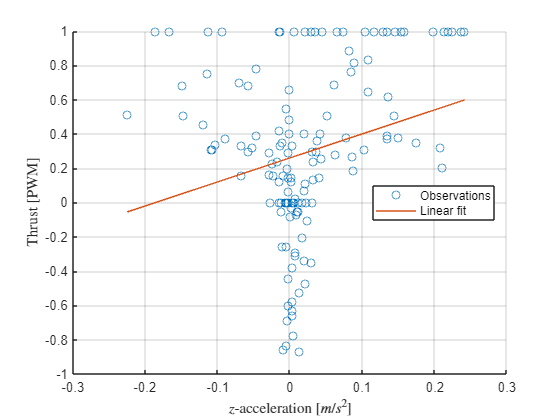

load("data/thrust_relation.mat")
start = 21;
imu = out.Acc_Z{2}.Values.Data(start:floor(end/2))-g;
pwm = out.Acc_Z{1}.Values.Data(start:floor(end/2));
xy = [imu,pwm];
xy = rmoutliers(xy);
scatter(xy(:,1), xy(:,2))
P = polyfit(xy(:,1), xy(:,2), 1);
yfit = P(1)*xy(:,1) + P(2);
hold on
plot(xy(:,1),yfit)
grid on
hold off
xlabel('$z$-acceleration $[m/s^2]$','Interpreter','Latex')
ylabel('Thrust [PWM]','Interpreter','Latex')
legend('Observations', 'Linear fit', Location='best')

### Exercise 7.2.2: Adjusting the controller

For our controller, we decided to use a PID controller as this has yielded the best results in practice. 

pos_kp = 0.6;
pos_ki = 0.01;
pos_kd = 0.3;

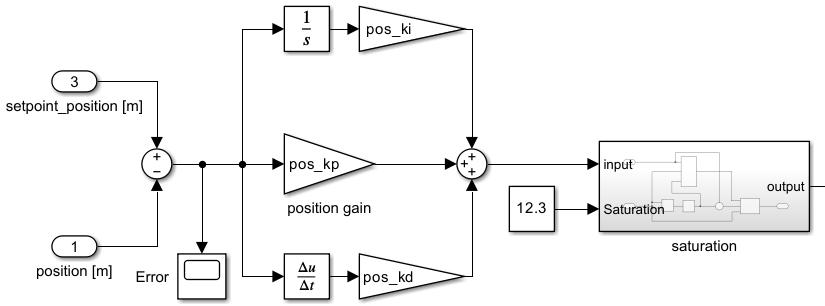

%% Relation between thrust and vertical acceleration
%pos_ki = 0.000033;
%vel_kp = 0.25;
PWM = 60000;
P = [1.3999, 0.2601] * PWM;

% Make route
Start_position = [1.80;-5.73; 0];
route = [0 0 1;
    1 0 1];
route(1,:) = route(1,:) + Start_position';
route(2,:) = route(2,:) + Start_position';

Handy commands

% roslaunch vrpn_client_ros sample.launch server:=192.168.1.129
% cfstart #

#### Exercise 7.2.2: Hovering 

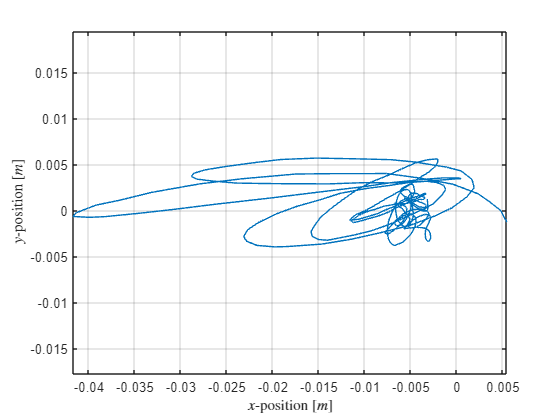

run = load("data/Run_7_2_part1.mat");
offset = [1.80;-5.73; 0];

x = run.out.Position.signals.values(:,1)-offset(1);
y = run.out.Position.signals.values(:,2)-offset(2);
z = run.out.Position.signals.values(:,3);
time = run.out.Position.time;

figure(1)
plot(x,y)
axis 'equal'
xlabel('$x$-position $[m]$','Interpreter','Latex')
ylabel('$y$-position $[m]$', 'Interpreter','Latex')
grid on

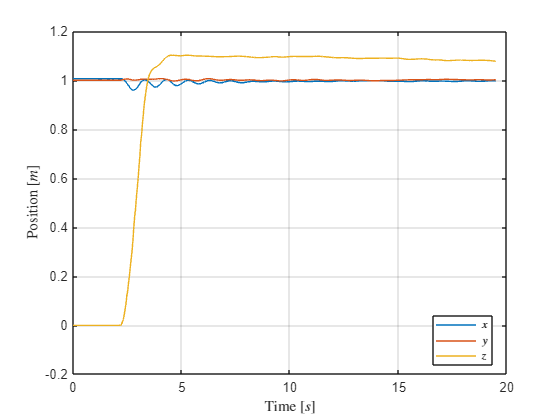


figure(2)
plot(time, [x+1,y+1,z]) % The +1 is just a formality
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Position $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on

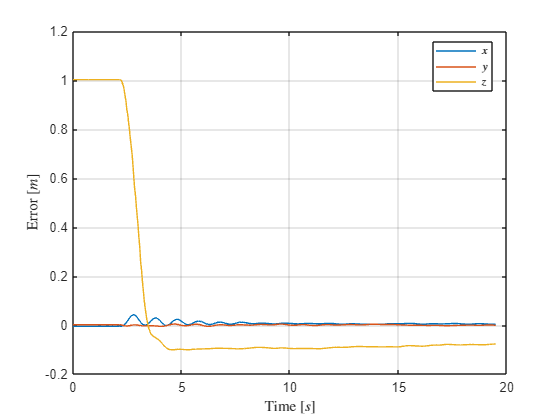


figure(3)
plot(time, squeeze(run.out.Error.signals.values))
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Error $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on

#### Exercise 7.2.2: Flying between two coordinates

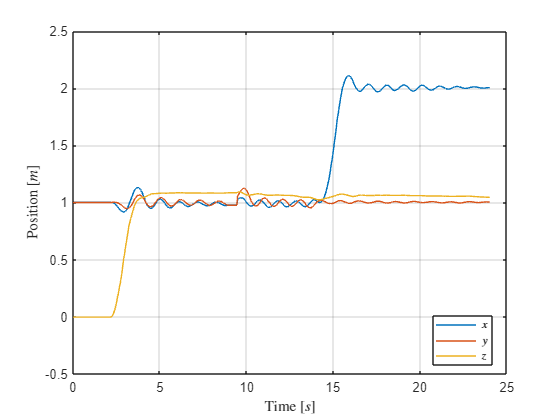

% Route used
go_to_position = [2.85;-5.69; 0];

% Make route
route = [0 0 1;
    1 0 1];
route(1,:) = route(1,:) + go_to_position';
route(2,:) = route(2,:) + go_to_position';

run = load("data/Run_7_2_part2.mat");
offset = [1.80;-5.73; 0];

x = run.out.Position.signals.values(:,1)-offset(1);
y = run.out.Position.signals.values(:,2)-offset(2);
z = run.out.Position.signals.values(:,3);
time = run.out.Position.time;

figure(1)
plot(x,y)
axis 'equal'
xlabel('$x$-position $[m]$','Interpreter','Latex')
ylabel('$y$-position $[m]$', 'Interpreter','Latex')
grid on
savepdf(figure(1), 'images/exe7_2_hover_xy')

figure(2)
plot(time, [x+1,y+1,z]) % The +1 is just a formality
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Position $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on

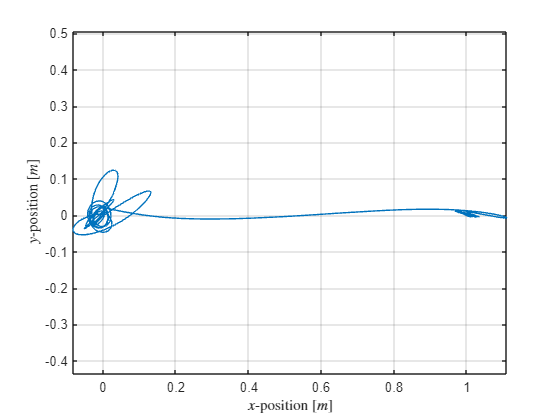

savepdf(figure(1), 'images/exe7_2_hover_xyz')

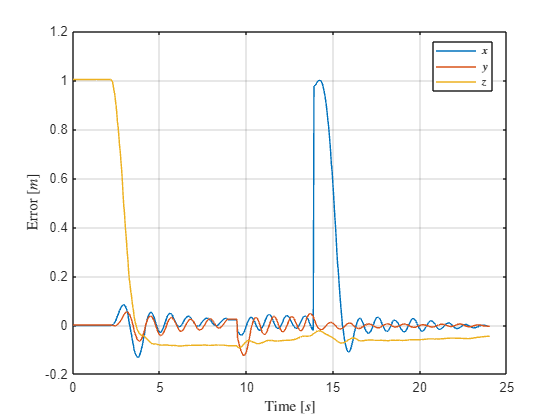


figure(3)
plot(time, squeeze(run.out.Error.signals.values))
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Error $[m]$', 'Interpreter','Latex')
legend('$x$', '$y$', '$z$', 'Interpreter','Latex', 'Location', 'best')
grid on
savepdf(figure(1), 'images/exe7_2_hover_error')

### Exe. 7.3

knots = [0 60];
waypoints = cell(1,2);
waypoints{1} = go_to_position;
waypoints{2} = go_to_position;
box_size = 0.01;
order = 12;
tot_time = 60;

coord1 = [2.44 -2.99 1.26];
coord4 = [0.56 -4.58 1.25];
coord3 = [-0.95 -2.77 1.24];
coord2 = [0.81 -1.45 1.28];

clf
% Get the corridors
corridors = pos_2_corridors(transpose(waypoints{1}), transpose(waypoints{2}), coord1, coord2, coord3, coord4, box_size, tot_time);

dist = 3.0830

dist = 2.2425

dist = 2.2004

dist = 2.3572

dist = 2.1030

Optimization will be performed on end derivatives. This will improve optimization performance.
solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!
Elapsed time is 0.035405 seconds.


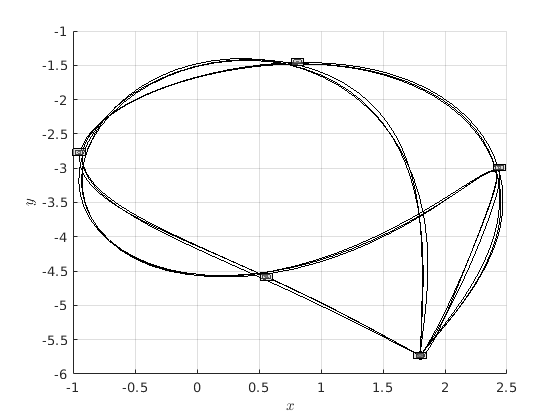

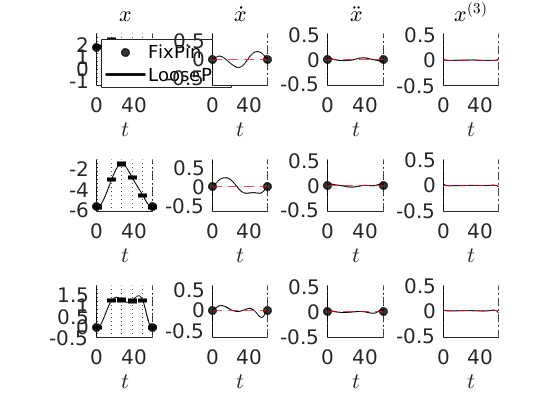

make_plots = true;

% Get the polynomial trajectory
poly_traj = uas_minimum_snap(knots, order, waypoints, corridors, make_plots);

poly_traj.polyCoeffSet

ans = 1×3 cell array
    {13×1 double}    {13×1 double}    {13×1 double}


function savepdf(figure, name)
    set(figure,'Units','Inches');
    pos = get(figure,'Position');
    set(figure,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
    print(figure, name,'-dpdf','-r0')
end
